# Kr-eve2 Analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

Figflag = 0;
cmap_temp = [[0 0.4470 0.7410];[0.8500 0.3250 0.0980];[0.9290 0.6940 0.1250];[0.4940 0.1840 0.5560]];

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/'];
mkdir(FigPath)

Now, load all the data

load('./data/inference_traces_Kruppel_eve2_pass1_dT20.mat')

Specify some parameters

numParticle = length(trace_struct_final);

APbinID = linspace(-20,20,41);

% left and right bound for quality control
LeftBound = 5;
RightBound = 15;

% Specify the bins we want to plot
binRange = 21:30;

%bin number
len = 20;

%time range to plot
TimeMin = 480;
TimeMax = 2400;

offset = 15E5;
%edges = linspace(2.4E5,4.4E5,len+1);
edges = linspace(0.3e7-offset,1.7e7-offset,len+1);

## Part 2: Fliter traces including quality control

First, we want to filter the traces based on SetID

dataID = 1; % We want to analyze "optoknirps_new_embryo6"
SetID_all = [trace_struct_final(:).setID]; % SetID for all the traces
%TraceIndex = find(SetID_all == dataID); % Trace index that we will analyze

Then, we can assign the traces to p-each AP bin

APPosition_mean = [trace_struct_final(:).MeanAP];
APbinData = discretize(APPosition_mean,APbinID);

Quality control: Only keep the traces that is continuous across specified time range

QualityFlag = zeros(numParticle,1);


for i = 1:numParticle
    MinTime = trace_struct_final(i).time_interp(1)/60;
    MaxTime = trace_struct_final(i).time_interp(end)/60;

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag(i) = 1;
    else
        QualityFlag(i) = 0;
    end
end

## Part 3: Compile promoter states

First, we will do this for the full bin range

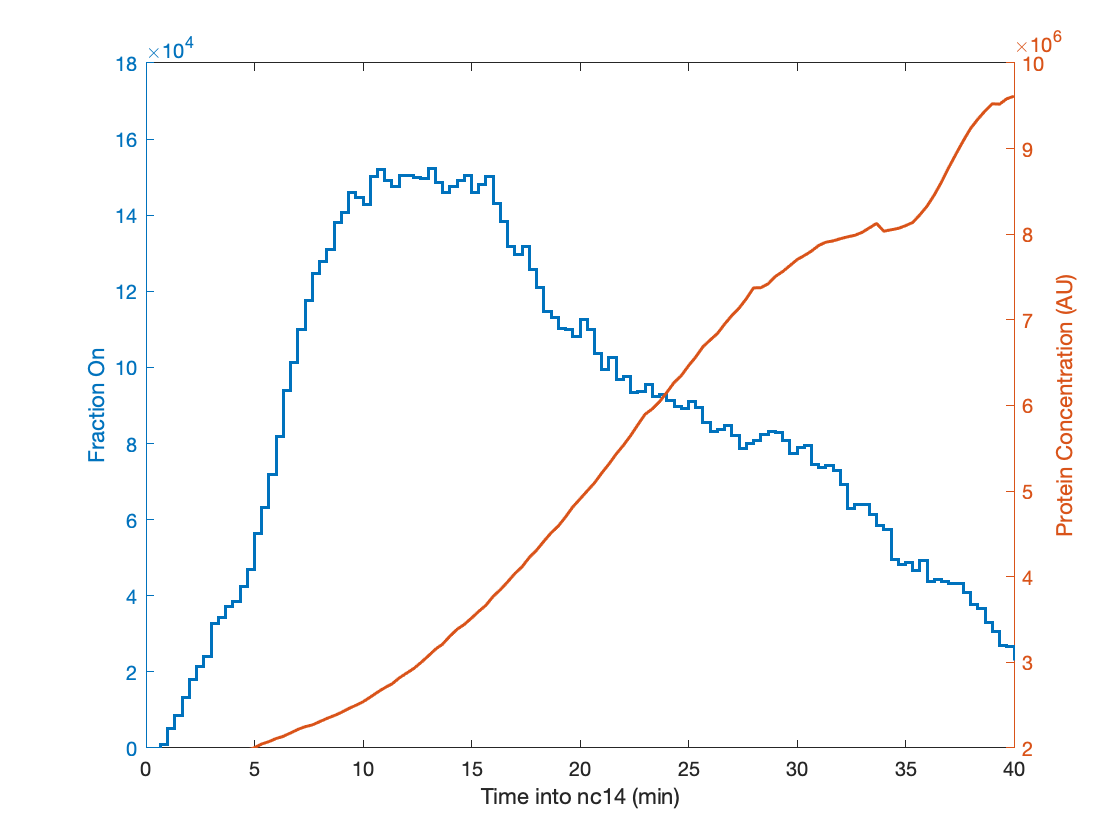

TimeRange = 0:20:2400;

% Initialize array for storage
TotalTrace = zeros(1,length(TimeRange));
ProteinTrace = zeros(1,length(TimeRange));
ProteinSum = zeros(1,length(TimeRange));
SpotSum = zeros(1,length(TimeRange));

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)) & QualityFlag');

% compile protein concentration and spot fluorescence
for i = TraceIndex
    TimePoint = trace_struct_final(i).time_interp;
    NuclearConc = trace_struct_final(i).protein_interp-offset;
    SpotFluo = trace_struct_final(i).fluo_interp;
    
    for j = 1:length(TimePoint)
        Index = find(TimeRange==TimePoint(j));

        TotalTrace(Index) = TotalTrace(Index)+1;
        SpotSum(Index) = SpotSum(Index)+SpotFluo(j);
        
        % compile protein concentration
        if ~isnan(NuclearConc(j))
            ProteinSum(Index) = ProteinSum(Index)+NuclearConc(j);
            ProteinTrace(Index) = ProteinTrace(Index)+1;
        end
    end
    
end

SpotAvr = SpotSum./TotalTrace;
ProteinAvr = ProteinSum./TotalTrace;

fig = figure;
yyaxis left
stairs(TimeRange/60,SpotAvr,'LineWidth',1.5)
ylabel('Fraction On')
ylim([0 18E4])
yyaxis right
plot(TimeRange/60,ProteinAvr,'LineWidth',1.5)
ylabel('Protein Concentration (AU)')
ylim([2E6 10E6])

%xlim([15,35])
xlabel('Time into nc14 (min)')

We can plot "input-output" function for it

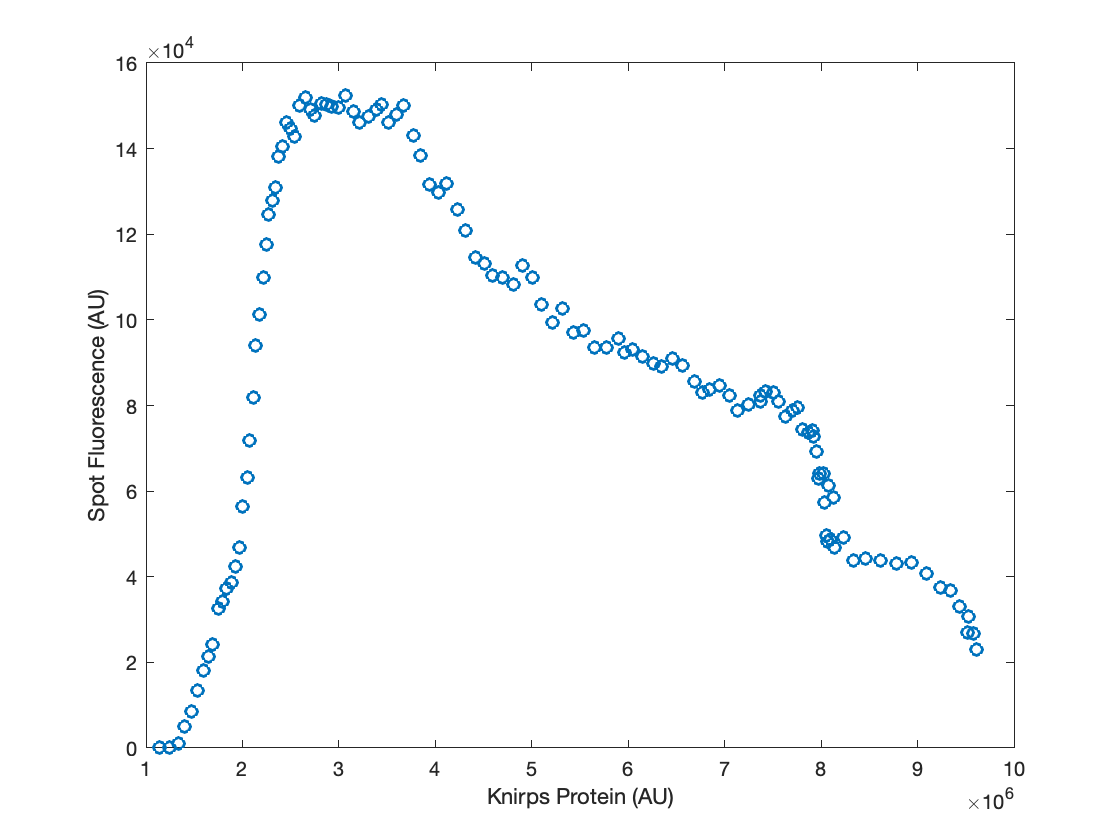

Fig = figure;
plot(ProteinAvr,SpotAvr,'o','LineWidth',1.5)
xlabel('Knirps Protein (AU)')
ylabel('Spot Fluorescence (AU)')

Next, we will calculate same value for different bins

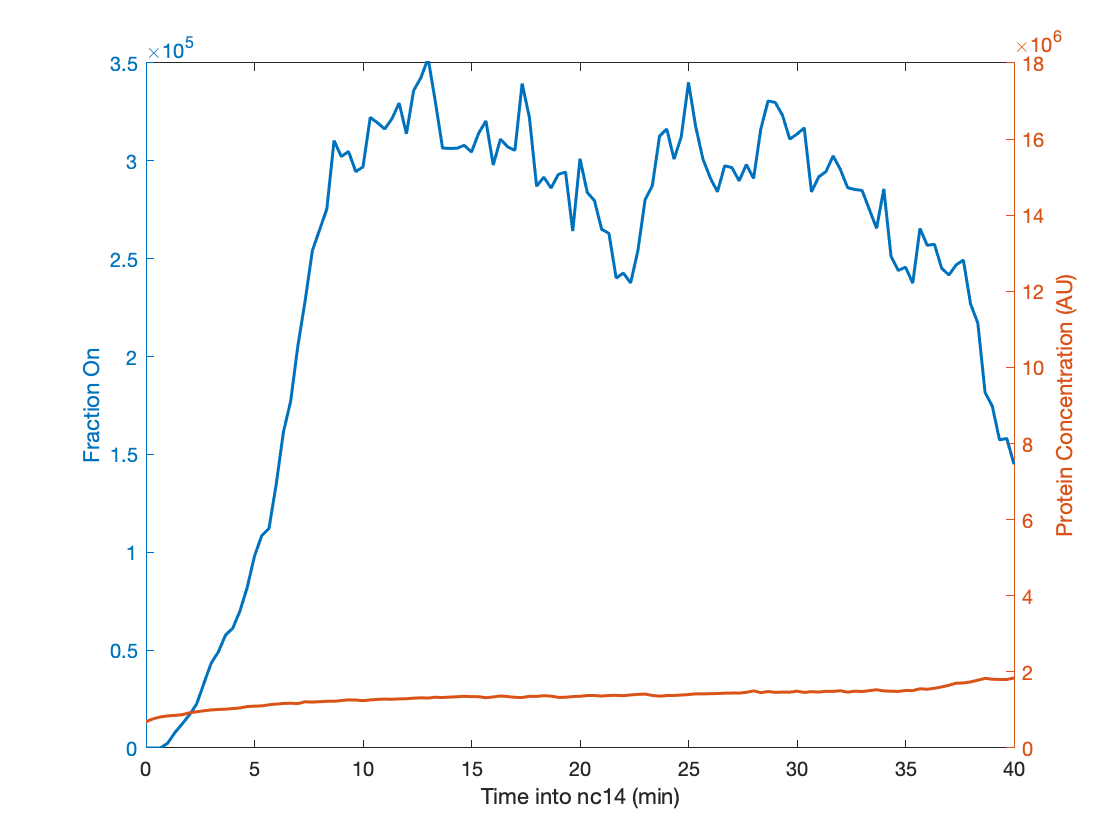

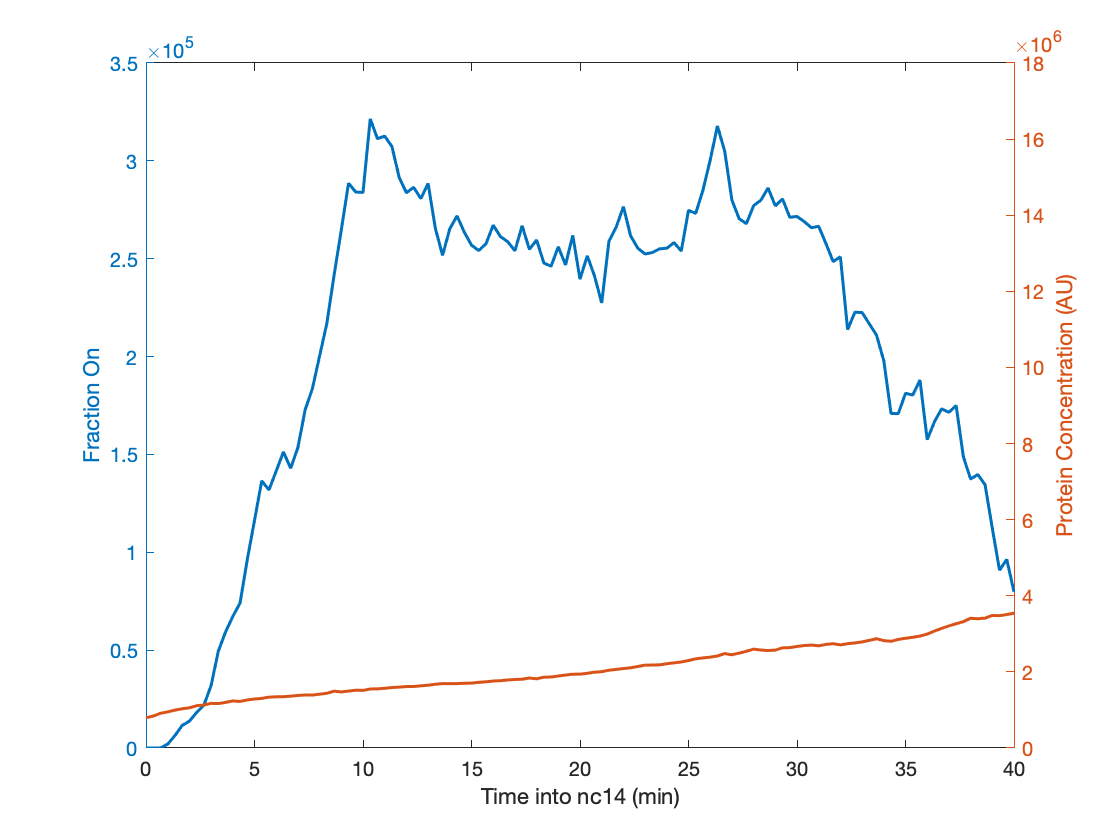

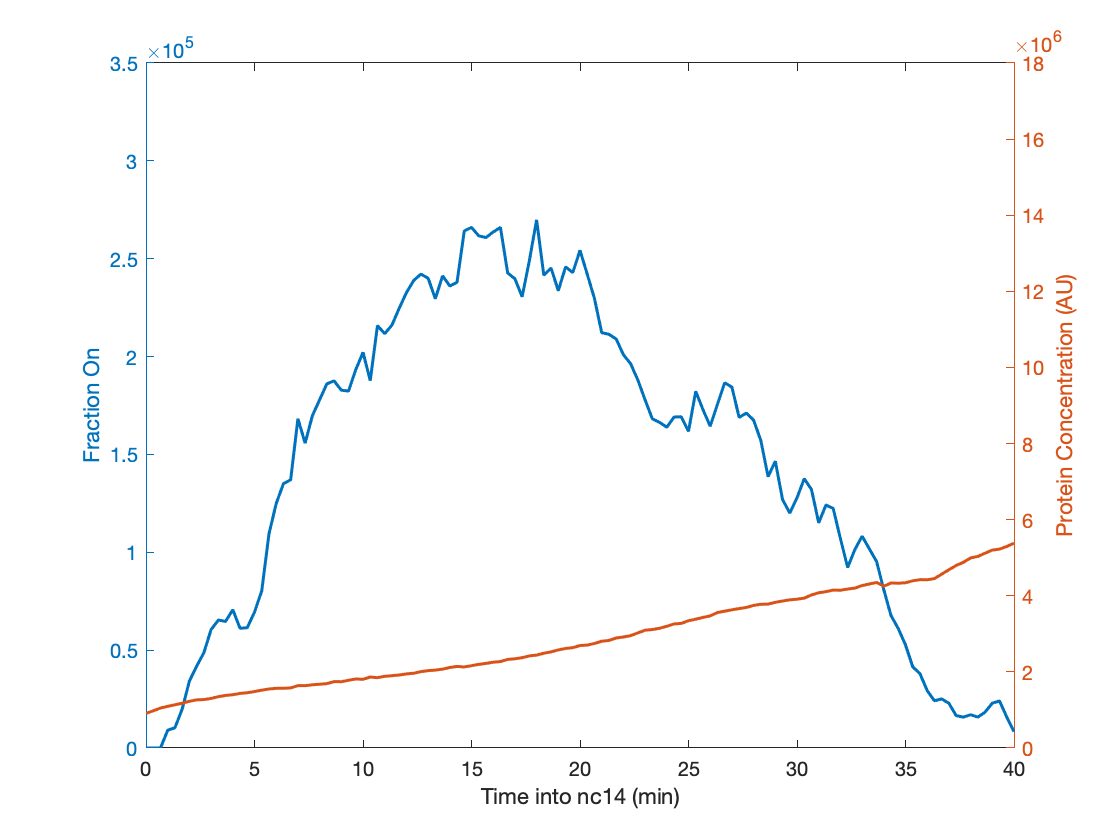

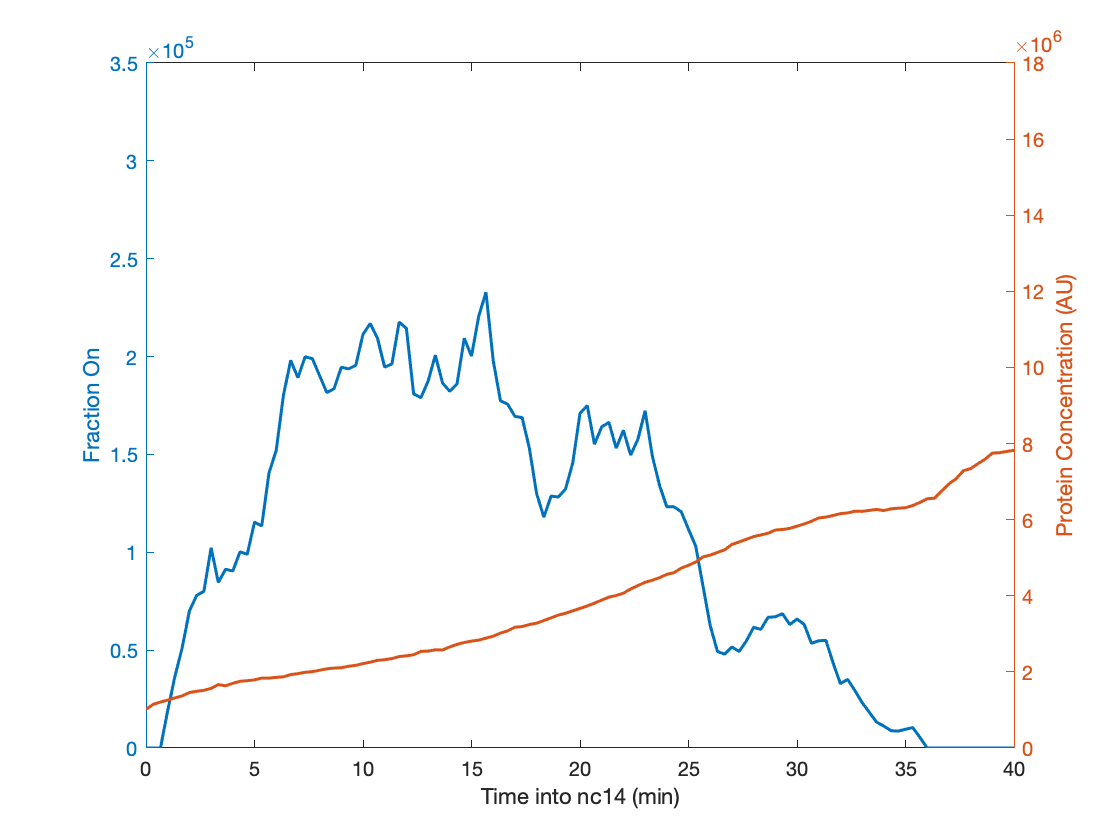

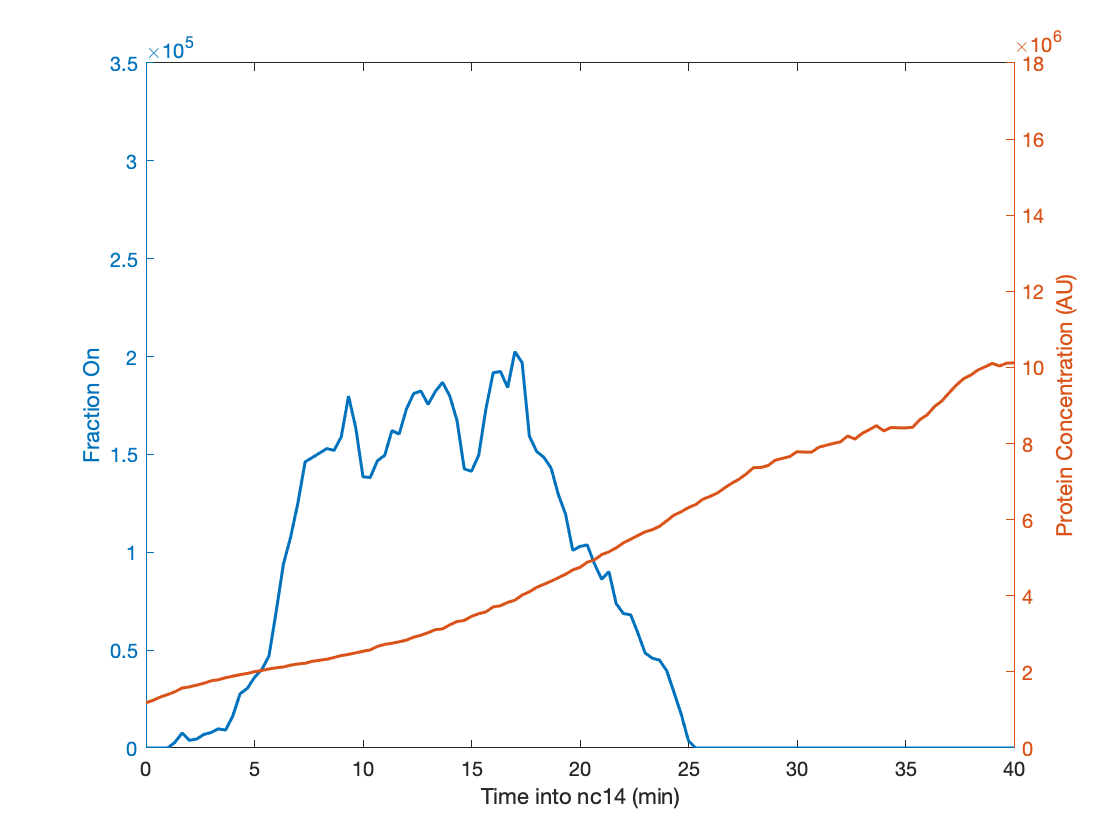

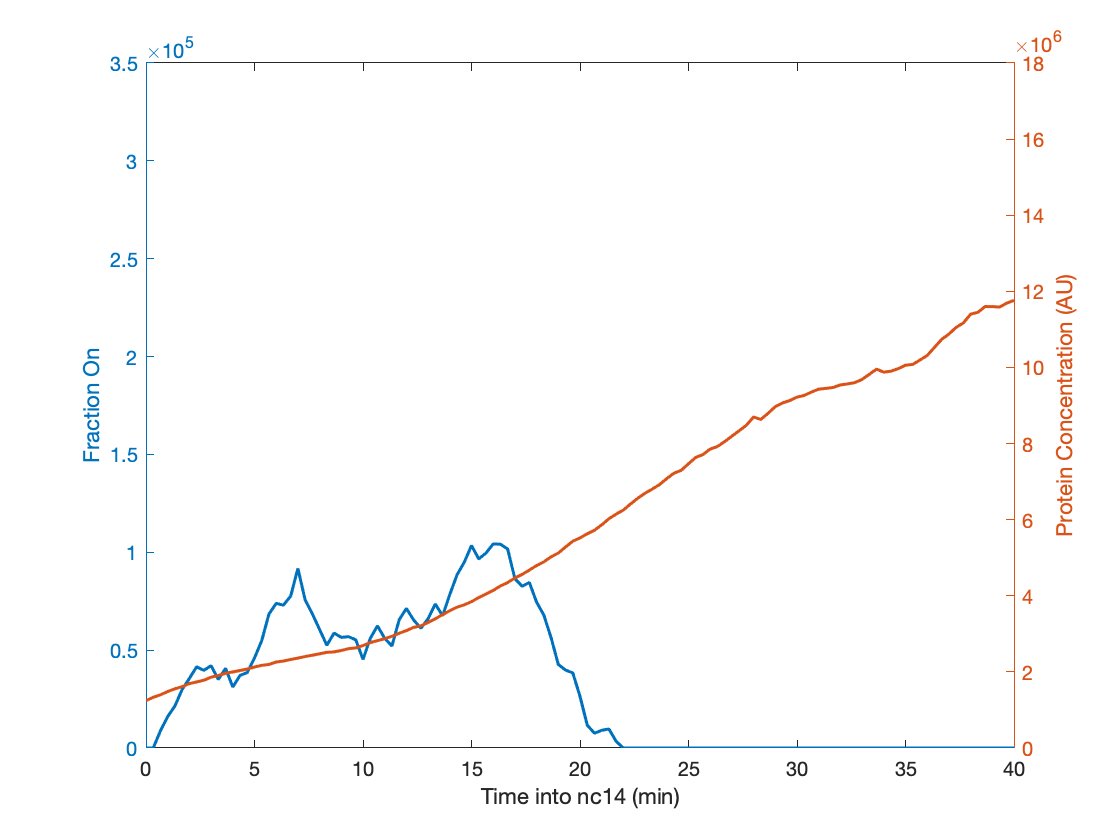

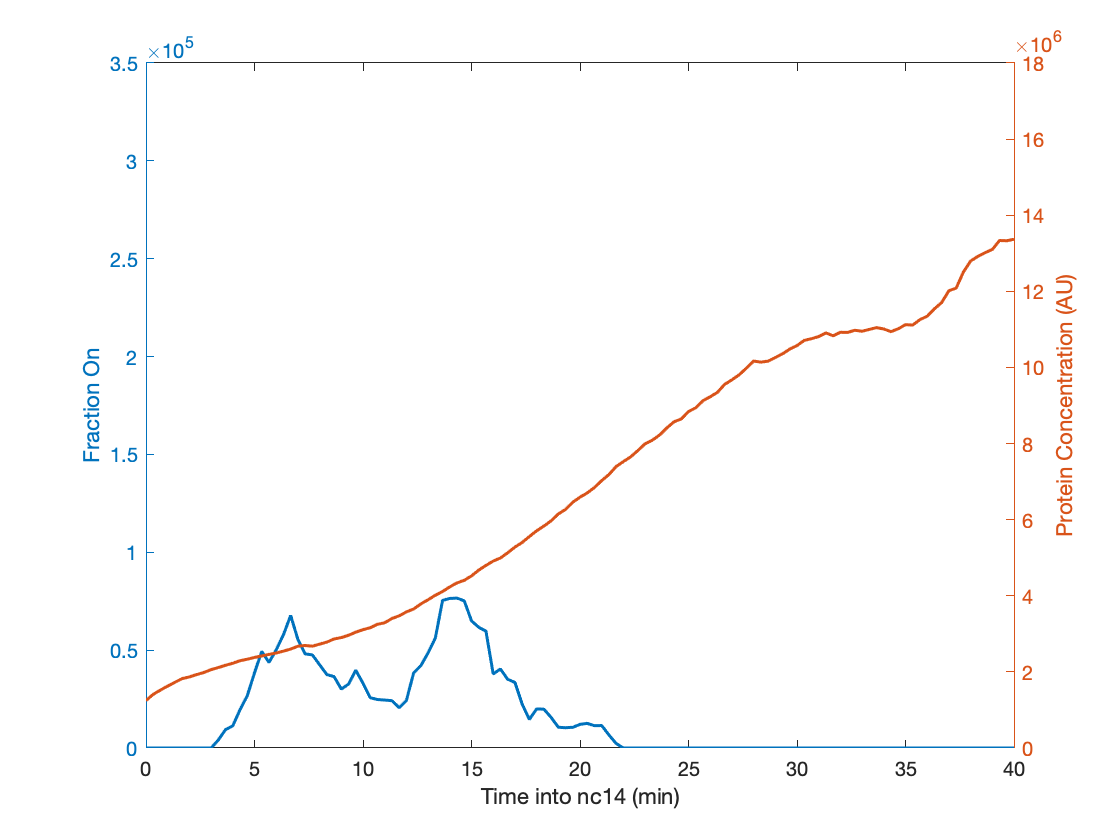

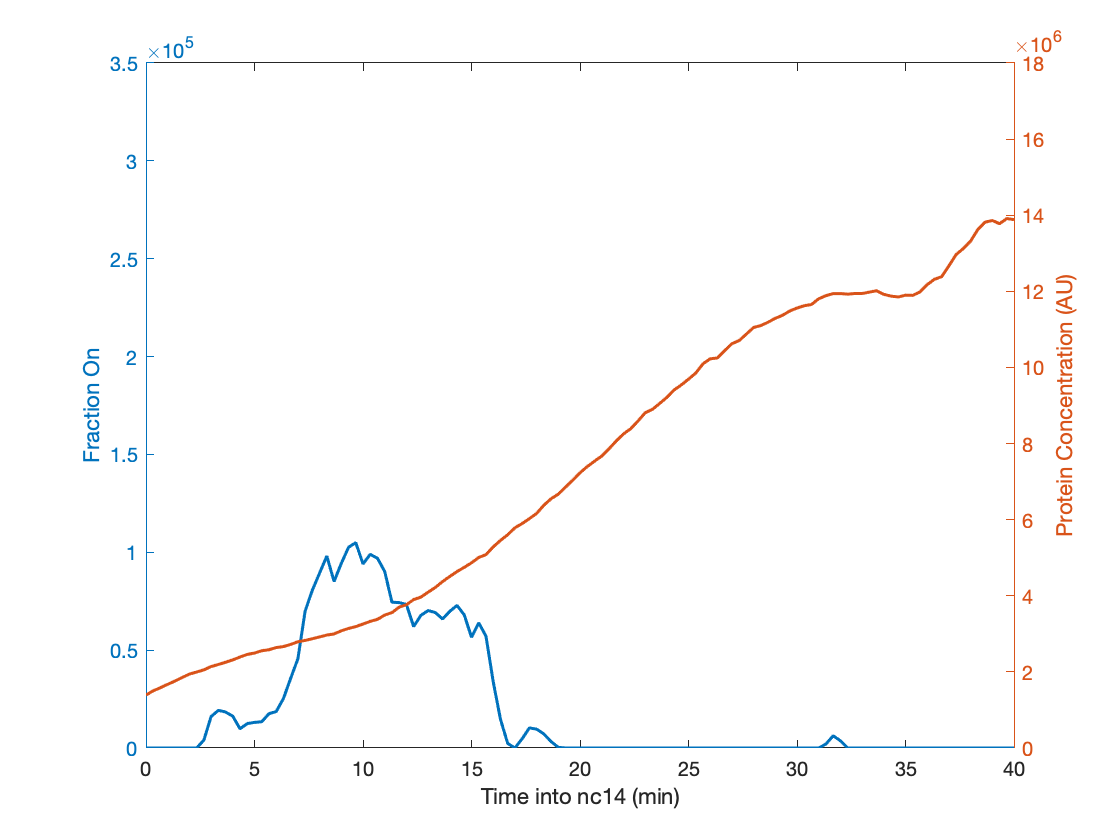

for i = binRange

    % Initialize array for storage
    TotalTrace = zeros(1,length(TimeRange));
    ProteinTrace = zeros(1,length(TimeRange));
    ProteinSum = zeros(1,length(TimeRange));
    SpotSum = zeros(1,length(TimeRange));
    
    TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,i)) & QualityFlag');
    
    % compile promoter states and protein concentration
    for j = TraceIndex
        TimePoint = trace_struct_final(j).time_interp;
        NuclearConc = trace_struct_final(j).protein_interp-offset;
        SpotFluo = trace_struct_final(j).fluo_interp;
        
        for k = 1:length(TimePoint)
            Index = find(TimeRange==TimePoint(k));

            TotalTrace(Index) = TotalTrace(Index)+1;
            SpotSum(Index) = SpotSum(Index)+SpotFluo(k);
            
            % compile protein concentration
            if ~isnan(NuclearConc(k))
                ProteinSum(Index) = ProteinSum(Index)+NuclearConc(k);
                ProteinTrace(Index) = ProteinTrace(Index)+1;
            end
        end
        
    end
    Fig = figure;
    yyaxis left
    plot(TimeRange/60,SpotSum./TotalTrace,'LineWidth',1.5)
    ylabel('Fraction On')
    ylim([0 3.5E5])
    yyaxis right
    plot(TimeRange/60,ProteinSum./ProteinTrace,'LineWidth',1.5)
    ylabel('Protein Concentration (AU)')
    ylim([0 18E6])
    
    %xlim([15,35])
    xlabel('Time into nc14 (min)')

end

Calculate input-output function from single particle traces

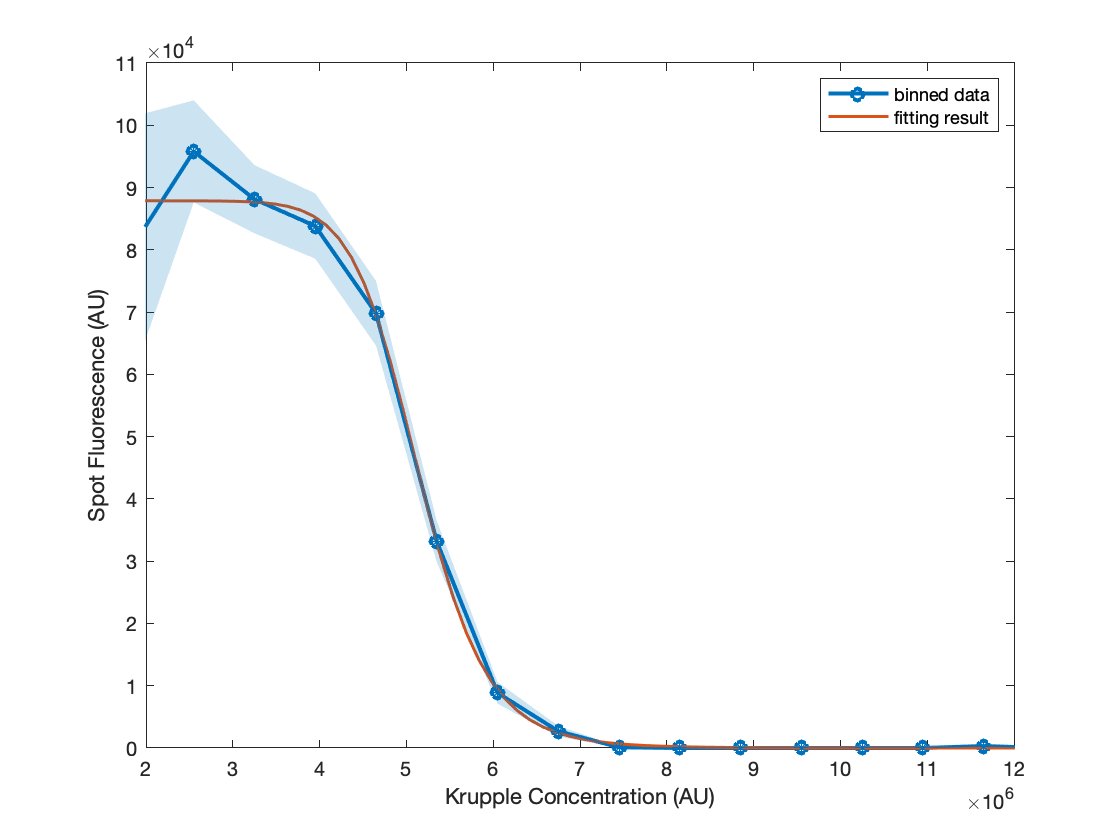

ProteinConc_all = [];
SpotFluo_all = [];

binRange_new = 25:30;
edges = linspace(0.3e7-offset,1.7e7-offset,len+1);

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange_new)) & QualityFlag');

for i = TraceIndex
    TimePoint = trace_struct_final(i).time_interp;
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_all = [ProteinConc_all trace_struct_final(i).protein_interp(j)-offset];
            SpotFluo_all = [SpotFluo_all trace_struct_final(i).fluo_interp(j)];
        end
    end
end
x = ProteinConc_all';
ys = SpotFluo_all';

%edges = quantile(x,len-1);
%edges = [min(x) edges];edges = [edges max(x)]; % add zero and max to left and right hand side of the array
%edges = linspace(min(ProteinConc_all), max(ProteinConc_all),len+1);
[~,~,loc]=histcounts(x,edges);
yplots = accumarray(loc(loc>0),ys(loc>0),[len 1])./accumarray(loc(loc>0),1,[len 1]);
errs = sqrt(accumarray(loc(loc>0),(ys(loc>0)).^2,[len 1])./accumarray(loc(loc>0),1,[len 1]))./sqrt(accumarray(loc(loc>0),1,[len 1]));

xmid = 0.5*(edges(1:end-1)+edges(2:end));


% generate fit
% specify fit type
fitname = 'a*K^n/(K^n+x^n)';
[io_fits,gof] = fit(xmid(:),yplots(:),fitname,'StartPoint',[0.5e7,18E5,10],'Lower',[0,0,0]);

xRange = double(linspace(min(ProteinConc_all), max(ProteinConc_all)));

fig = figure;
plot(xmid,yplots,'-o','LineWidth',2)
hold on
plot(xRange,io_fits(xRange),'LineWidth',1.5)
boundedline(xmid, yplots, errs,'-*','nan', 'gap','alpha','cmap', cmap_temp(1,:));
xlim([0.2E7 1.2E7])
ylim([0 11E4])
xlabel('Krupple Concentration (AU)')
ylabel('Spot Fluorescence (AU)')

legend('binned data','fitting result')